# ACS6116 - Rocket Control - Main

clc; clear; close all;

## Problem Definition

### Define Constants

syms mass   % rocket mass
syms g      % gravity (defined as 9.81 further on)  
syms T      % sampling time

### Define Dimensions

%syms k;                     % time dimension (discrete) 
syms r_x r_y r_z;           % rocket coordinates in x,y,z
syms v_x v_y v_z;           % rocket velocity in x,y,z directions

### Defining Functions

syms f_x f_y f_z;           % thrust in 3 dimensions

%f = [f_x; f_y; f_z-mass*g]
f = [f_x; f_y; f_z;]

$$f = \left(\begin{array}{c} f_{x}\\ f_{y}\\ f_{z} \end{array}\right)$$

r = [r_x; r_y; r_z;];       % bold faced vector of coordinates
v = [v_x; v_y; v_z;];       % bold faced vector of velocities
x = [r; v;]

$$x = \left(\begin{array}{c} r_{x}\\ r_{y}\\ r_{z}\\ v_{x}\\ v_{y}\\ v_{z} \end{array}\right)$$

delta = [1; 1; -g*mass;];

### Rocket Dynamics Model

A = [   eye(3), eye(3)*T; 
        zeros(3), eye(3);   ]

$$A = \left(\begin{array}{cccccc} 1 & 0 & 0 & T & 0 & 0\\ 0 & 1 & 0 & 0 & T & 0\\ 0 & 0 & 1 & 0 & 0 & T\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

B=(1/mass)*[    0.5*T^2*eye(3); 
                    T*eye(3);   ]

$$B = \left(\begin{array}{ccc} \frac{T^{2}}{2\,\mathrm{mass}} & 0 & 0\\ 0 & \frac{T^{2}}{2\,\mathrm{mass}} & 0\\ 0 & 0 & \frac{T^{2}}{2\,\mathrm{mass}}\\ \frac{T}{\mathrm{mass}} & 0 & 0\\ 0 & \frac{T}{\mathrm{mass}} & 0\\ 0 & 0 & \frac{T}{\mathrm{mass}} \end{array}\right)$$

C = eye(6); 
% C = [   eye(3),     zeros(3);
%         zeros(3),   zeros(3);   ]  

% dimensions
n = size(A,1);  % number of states
m = size(B,2);  % number of inputs
p = size(C,1);  % number of outputs

%dynamic_model(k) = [r(k+1); v(k+1);] == A*[r(k); v(k);] + B*f(k)
%x_dot = A*x + B*f %+ B*delta
x_dot = A*x + B*f + B*delta

$$x\_dot = \begin{array}{l} \left(\begin{array}{c} r_{x}+T\,v_{x}+\sigma_{1}+\frac{T^{2}\,f_{x}}{2\,\mathrm{mass}}\\ r_{y}+T\,v_{y}+\sigma_{1}+\frac{T^{2}\,f_{y}}{2\,\mathrm{mass}}\\ r_{z}+T\,v_{z}-\frac{T^{2}\,g}{2}+\frac{T^{2}\,f_{z}}{2\,\mathrm{mass}}\\ v_{x}+\frac{T}{\mathrm{mass}}+\frac{T\,f_{x}}{\mathrm{mass}}\\ v_{y}+\frac{T}{\mathrm{mass}}+\frac{T\,f_{y}}{\mathrm{mass}}\\ v_{z}-T\,g+\frac{T\,f_{z}}{\mathrm{mass}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{T^{2}}{2\,\mathrm{mass}} \end{array}$$

y = C*x

$$y = \left(\begin{array}{c} r_{x}\\ r_{y}\\ r_{z}\\ v_{x}\\ v_{y}\\ v_{z} \end{array}\right)$$

Note that this a dynamic model in the form:


$$x\left(k+1\right)=A*x\left(k\right)+B*u\left(k\right)\;\textrm{and},\;y\left(k\right)=C*x\left(k\right)$$


#### Input Constraint Matrices:

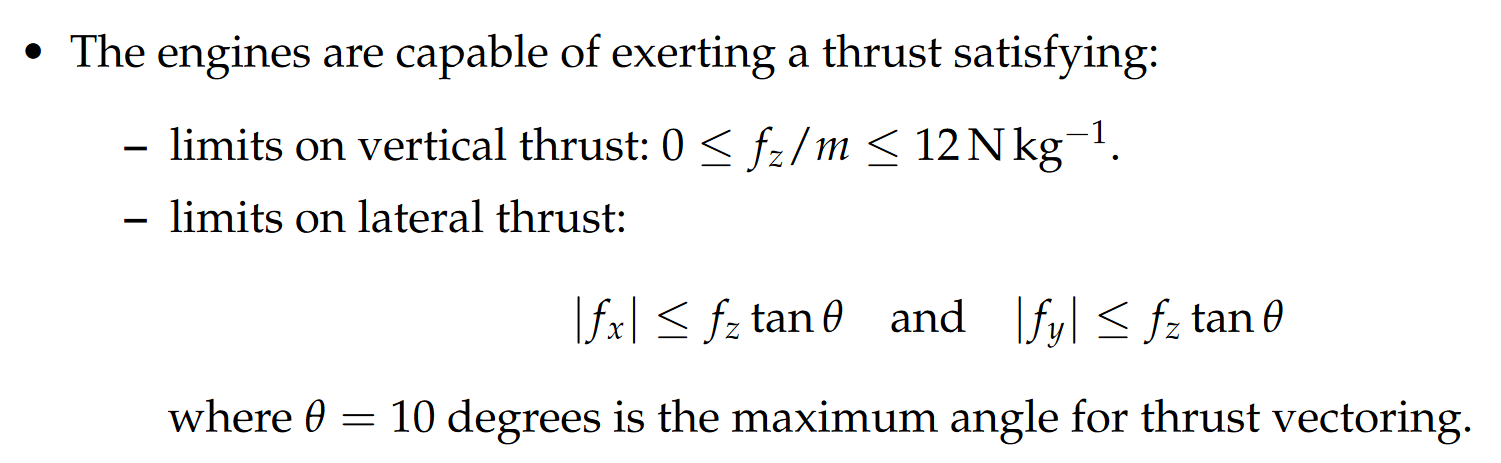

syms theta
qu = [  % Input constraints
    g*mass*tan(theta);  % f_x Upper limit
    g*mass*tan(theta);  % f_y Upper limit
    12*mass-g*mass;     % f_z Upper limit (subtracting gravity acting downwards)
    %12*mass
    g*mass*tan(theta);  % f_x Lower limit
    g*mass*tan(theta);  % f_y Lower limit
    g*mass;             % f_z Lower limit (zero thrust, gravity acting downwards)
], %Pu = [+eye(m); -eye(m);];   
Pu = [
    1   0   -1*tan(theta)
    0   1   -1*tan(theta)
    0   0   1
    -1  0   -1*tan(theta)
    0   -1  -1*tan(theta)
    0   0   -1
]
% qu = [  % Input constraints
%     0;  % f_x Upper limit
%     0;  % f_y Upper limit
%     12*mass;     % f_z Upper limit (subtracting gravity acting downwards)
%     %12*mass
%     0;  % f_x Lower limit
%     0;  % f_y Lower limit
%     0;             % f_z Lower limit (zero thrust, gravity acting downwards)
% ], %Pu = [+eye(m); -eye(m);];   

$$qu = \left(\begin{array}{c} 0\\ 0\\ 12\,\mathrm{mass}\\ 0\\ 0\\ 0 \end{array}\right)$$

% Pu = [
%     1   0   -1*tan(theta)
%     0   1   -1*tan(theta)
%     0   0   1
%     -1  0   -1*tan(theta)
%     0   -1  -1*tan(theta)
%     0   0   -1
% ]

$$Pu = \left(\begin{array}{ccc} 1 & 0 & -\tan\left(\theta \right)\\ 0 & 1 & -\tan\left(\theta \right)\\ 0 & 0 & 1\\ -1 & 0 & -\tan\left(\theta \right)\\ 0 & -1 & -\tan\left(\theta \right)\\ 0 & 0 & -1 \end{array}\right)$$

input_constraints = Pu*f <= qu

$$input\_constraints = \left(\begin{array}{c} f_{x}-f_{z}\,\tan\left(\theta \right)\leq 0\\ f_{y}-f_{z}\,\tan\left(\theta \right)\leq 0\\ f_{z}\leq 12\,\mathrm{mass}\\ -f_{x}-f_{z}\,\tan\left(\theta \right)\leq 0\\ -f_{y}-f_{z}\,\tan\left(\theta \right)\leq 0\\ -f_{z}\leq 0 \end{array}\right)$$

theta = deg2rad(10);

#### State Constraint Matrices:

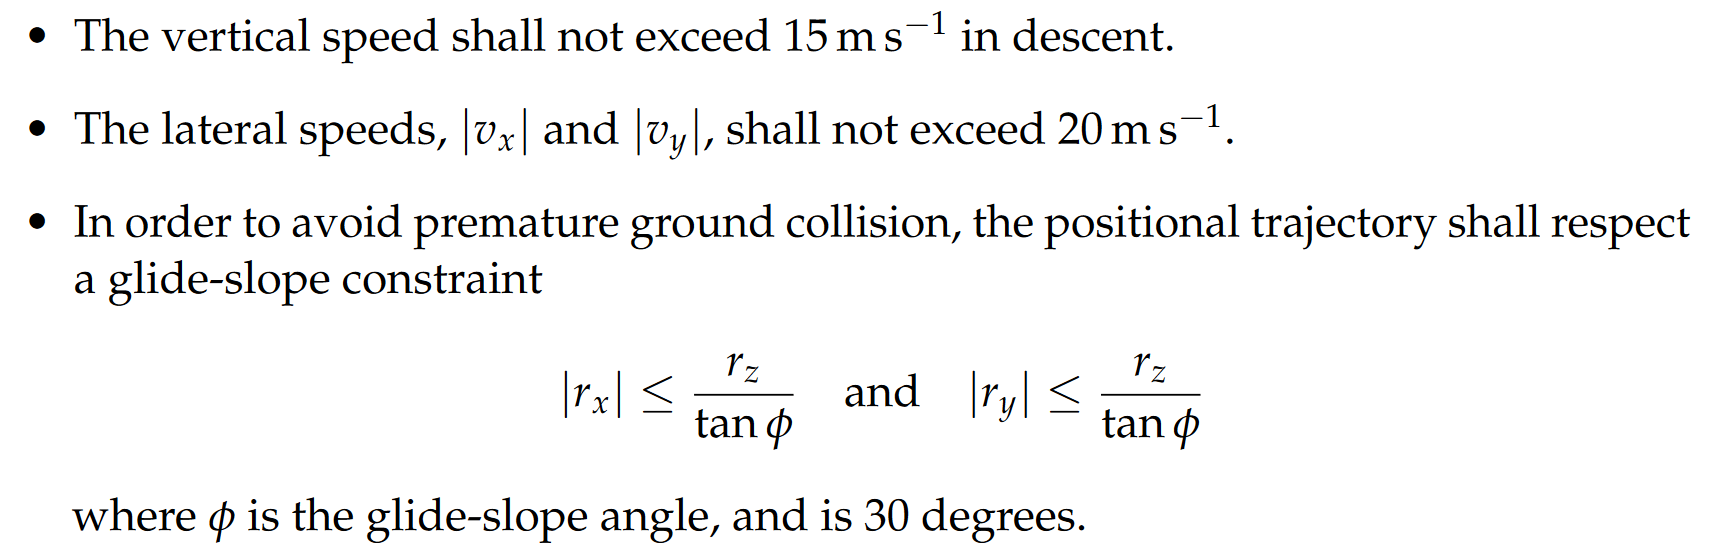

syms phi
qx = [  % State Constraints
    0;      % X Upper limit, complying with glide-slope angle
    0;      % Y Upper limit, complying with glide-slope angle
    inf;    % Z position Upper limit
    20;     % "the lateral speeds, |vx| and |vy|, shall not exceed 20 m/s"
    20;     %  ^^^
    inf;    % no upper limit on Z velocity
    0;      % X Lower limit, complying with glide-slope angle
    0;      % Y Lower limit, complying with glide-slope angle
    0;      % the rocket cannot go beneath the ground level
    20;     % "the lateral speeds, |vx| and |vy|, shall not exceed 20 m/s"
    20;     %  ^^^
    15;     % "the vertical speed shall not exceed 15 m/s in descent"
],  %Px = [+eye(n); -eye(n);];

qx =      0
     0
   Inf
    20
    20
   Inf
     0
     0
     0
    20


Px = [
    1 0 -1/(tan(phi)) 0 0 0
    0 1 -1/(tan(phi)) 0 0 0
    0 0 1             0 0 0
    0 0 0 1 0 0
    0 0 0 0 1 0
    0 0 0 0 0 1
    -1 0 -1/(tan(phi)) 0 0 0
    0 -1 -1/(tan(phi)) 0 0 0
    0 0 -1 0 0 0
    0 0 0 -1 0 0
    0 0 0 0 -1 0
    0 0 0 0 0 -1
]

$$Px = \begin{array}{l} \left(\begin{array}{cccccc} 1 & 0 & \sigma_{1} & 0 & 0 & 0\\ 0 & 1 & \sigma_{1} & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ -1 & 0 & \sigma_{1} & 0 & 0 & 0\\ 0 & -1 & \sigma_{1} & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{1}{\tan\left(\varphi \right)} \end{array}$$

state_constraints = Px*x <= qx

$$state\_constraints = \left(\begin{array}{c} r_{x}-\frac{r_{z}}{\tan\left(\varphi \right)}\leq 0\\ r_{y}-\frac{r_{z}}{\tan\left(\varphi \right)}\leq 0\\ r_{z}\leq \infty \\ v_{x}\leq 20\\ v_{y}\leq 20\\ v_{z}\leq \infty \\ -r_{x}-\frac{r_{z}}{\tan\left(\varphi \right)}\leq 0\\ -r_{y}-\frac{r_{z}}{\tan\left(\varphi \right)}\leq 0\\ -r_{z}\leq 0\\ -v_{x}\leq 20\\ -v_{y}\leq 20\\ -v_{z}\leq 15 \end{array}\right)$$

phi = deg2rad(30);

### Problem Goal

The goal is to steer the rocket from an initial position $\mathit{\mathbf{r}}\left(0\right)$and velocity $\mathit{\mathbf{v}}\left(0\right)$to the target ground position ${\mathit{\mathbf{r}}}_t =0$at rest (${\mathit{\mathbf{r}}}_t =0$). This should be done *safely *and at *minimum fuel cost*.  This implies the following constraints:

#### Constraints

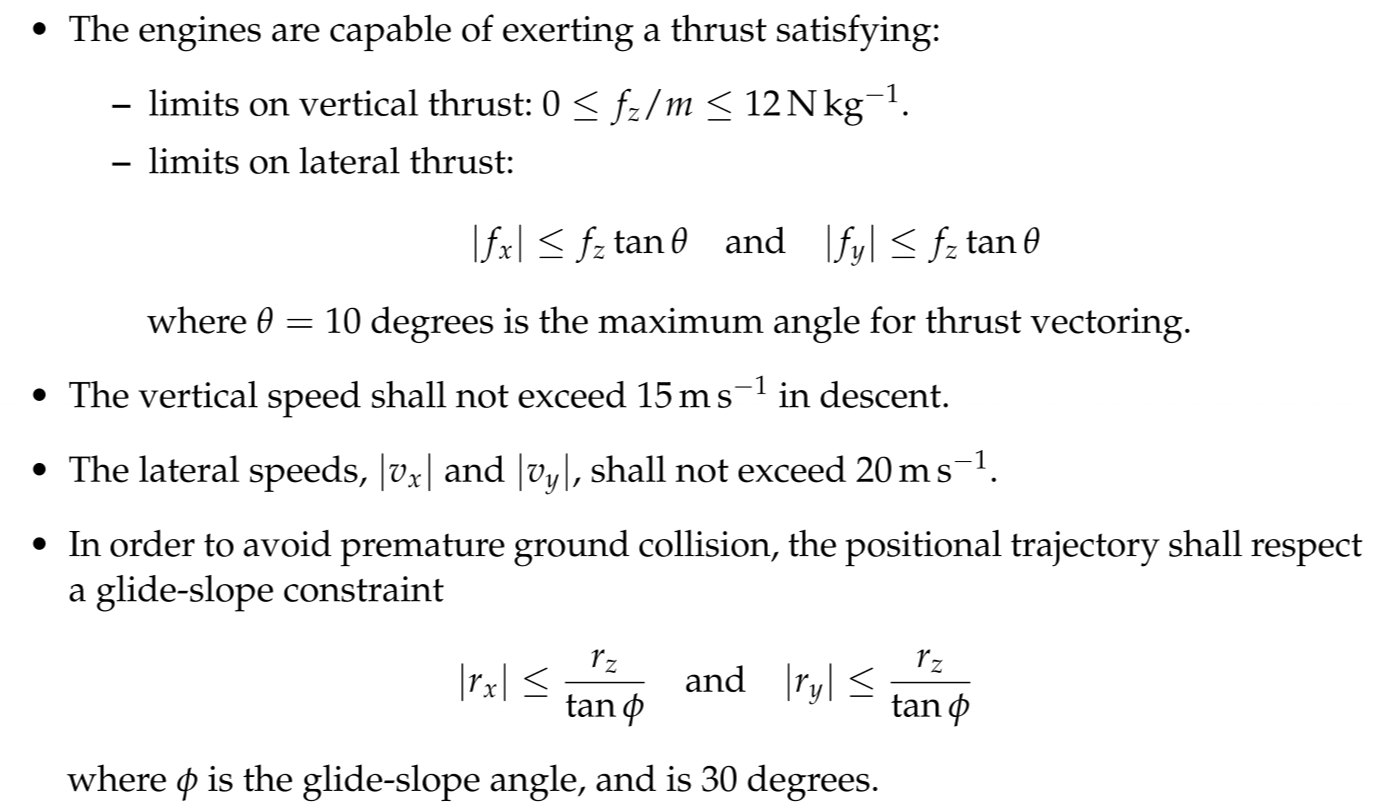

#### Target Set

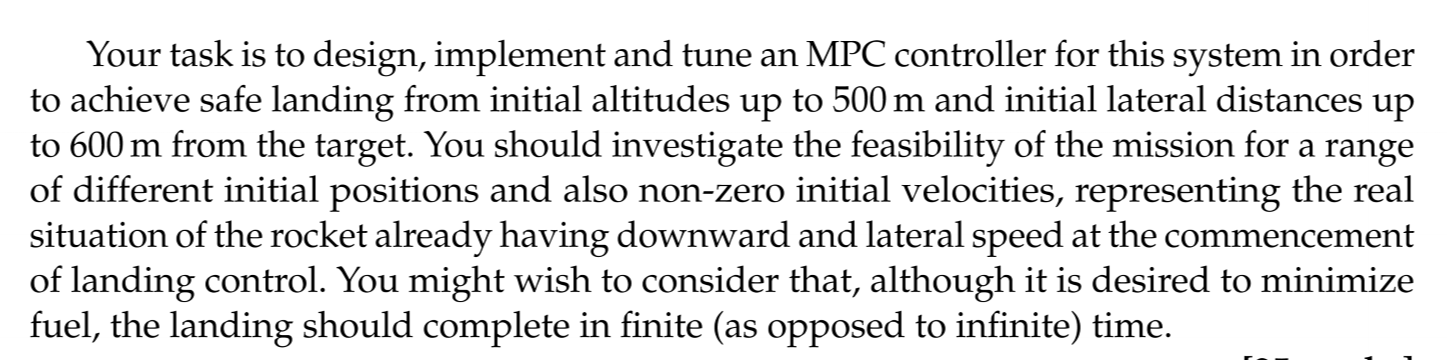

## Solution

T = 0.5;    % sampling time is 0.5s
g = 9.81;   % assuming earth gravity
mass = 1;   % simplifying rocket mass

A = double(subs(A));    B = double(subs(B));

% Controllability and Observability
Rc = ctrb(A,B), rank(ctrb(A,B))

Rc =     0.1250         0         0    0.3750         0         0    0.6250         0         0    0.8750         0         0    1.1250         0         0    1.3750         0         0
         0    0.1250         0         0    0.3750         0         0    0.6250         0         0    0.8750         0         0    1.1250         0         0    1.3750         0
         0         0    0.1250         0         0    0.3750         0         0    0.6250         0         0    0.8750         0         0    1.1250         0         0    1.3750
    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0         0
         0    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0         0    0.5000         0
         0         0    0.5000         0         0    0.5000         0         0    0.5000

ans = 6

Oc = obsv(A,C), rank(obsv(A,C))

Oc =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    1.0000         0         0    0.5000         0         0
         0    1.0000         0         0    0.5000         0
         0         0    1.0000         0         0    0.5000
         0         0         0    1.0000         0         0


ans = 6


% Cost Penalty Matrix Design
Q = C'*C;       % Q needs to be equal to the size of the states
R = 1*eye(m);   %R=eye(3);   % R needs to be equal to the size of the inputs
P=0*Q;          %P=Q;

% Controller Horizon Length
N = 12; 

% Initial states, at rest and at (200, 200, 600)m away from the target
x0 = [350 200 500 0 0 0]'

x0 =    350
   200
   500
     0
     0
     0



% Simulation Length
nk = 100;

### Zero Control Effort Response

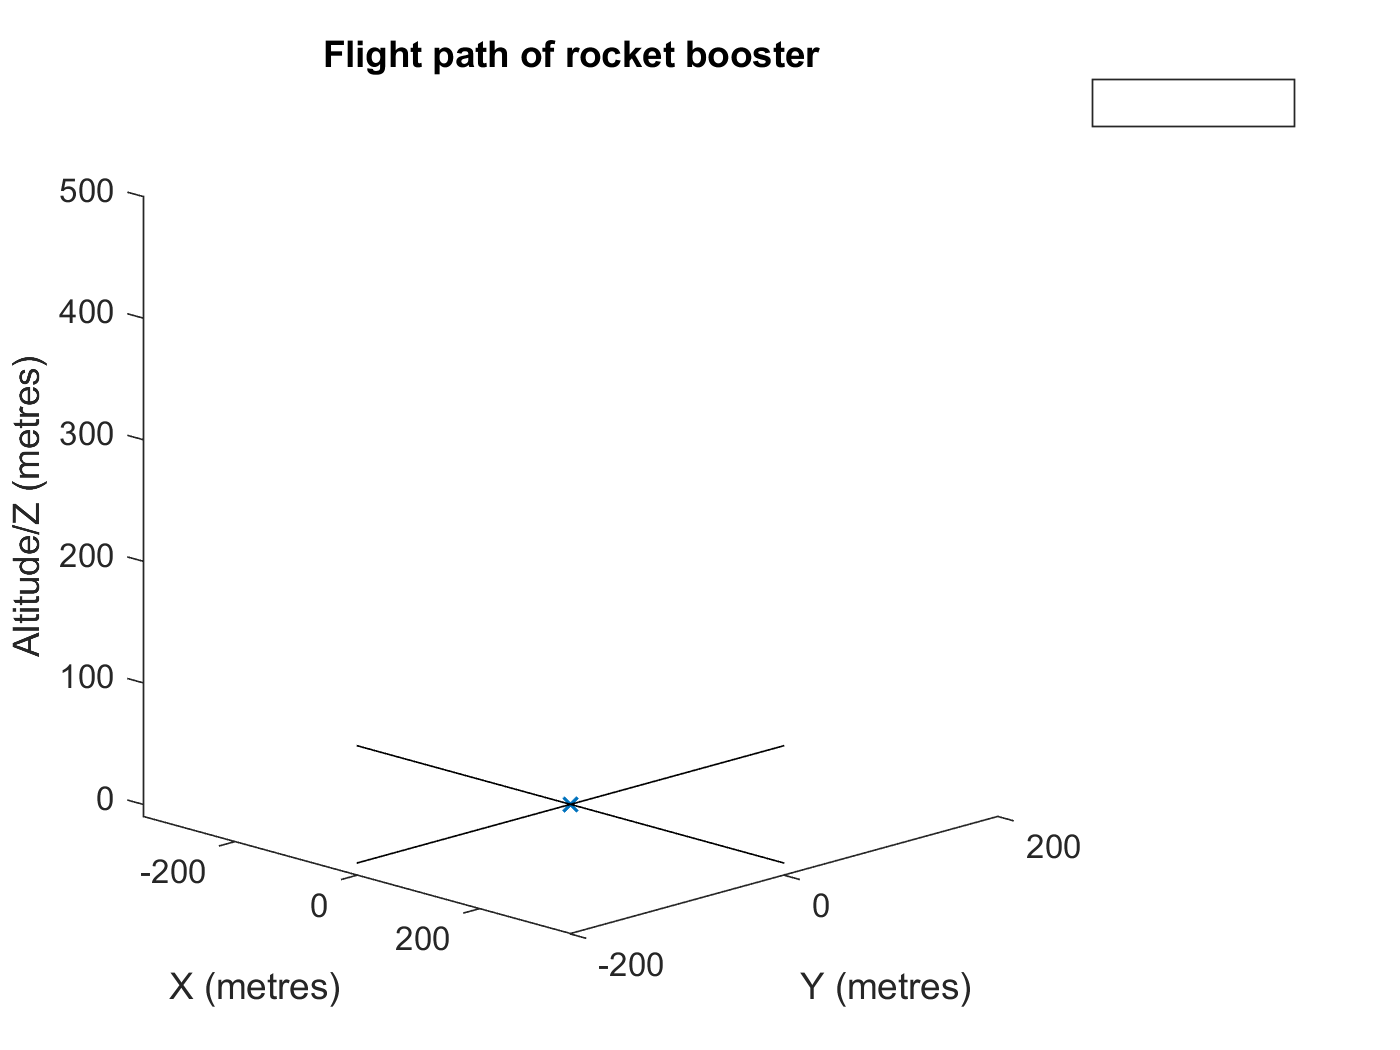

% % Zero control effort response: 
% %f_x = 0; f_y = 0; f_z = 0;  f = double(subs(f)), u = f
% 
% % Simulate
% x = x0;
% for k = 1:nk    % Safety Limit
%     % get current u and y
%     u = [0 0 0]'; 
%     y = C*x;
%     
%     % store
%     ys(:,k+1) = y;  
%     us(:,k+1) = u; 
%     xs(:,k+1) = x;
%     
%     % move
%     x = A*x + B*u;
% end
% xs = [x0 xs];

figure(1);
h(1) = plot3(0,0,0,'x', "LineWidth",1);                            
hold on;    set( get( get( h(1), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
h(2) = plot3([0 0],[-600 600],[0 0], 'Color', 'black', "LineWidth",.5);   
hold on;    set( get( get( h(2), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
h(3) = plot3([-600 600],[0 0],[0 0], 'Color', 'black', "LineWidth",.5);   
hold on;    set( get( get( h(3), 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );

%plot3(xs(1,:), xs(2,:), xs(3,:), "--", 'DisplayName', "Zero Control Response"); hold on; %legend show
xlabel("X (metres)");           xlim([-x0(1)    x0(1)]);    %xticks([0 xs(1,1)]);
ylabel("Y (metres)");           ylim([-x0(2)    x0(2)]);    %yticks([0 xs(2,1)]);
zlabel("Altitude/Z (metres)");  zlim([-10       x0(3)]);    %zticks([0 xs(3,1)]);
view(45,15);    title("Flight path of rocket booster"); legend show

### Receding-Horizon Constrained LQ-MPC

% Mode-2 K and P
K = -dlqr(A,B,Q,100*R); %K = [1.5 -1];
P = dlyap((A+B*K)',Q + K'*R*K);

% Update constraint matrices
Pu = double(subs(Pu));  qu = double(subs(qu))

qu =      0
     0
    12
     0
     0
     0


Px = double(subs(Px));  qx = double(subs(qx))

qx =      0
     0
   Inf
    20
    20
   Inf
     0
     0
     0
    20



% build the controller
[F, G] = predict_mats(A,B,N);                               % prediction matrices
[H, L, M] = cost_mats(F,G,Q,R,P);                           % cost matrices

% Constraint matrices
[Pc, qc, Sc] = constraint_mats(F,G, Pu,qu, Px,qx, Px,qx);  % put constraints in form Pc*U <= qc + Sc*x

% initialize
x = x0;
ys = zeros(p,nk);   
us = zeros(m,nk);

% loop
for k = 2:nk    
    % solve optimization problem
    [Uopt, fval, flag] = quadprog(H, L*x, Pc, qc+Sc*x);    % Solves optimum at each time step
    
    if (flag ~= (0||1))
        disp("Quadratic Programming error"), break;
    end
    
    % get uopt
    uopt = Uopt(1:m,:); % extracts the first input in the sequence for each state
    
    % store
    us(:,k) = uopt;
    ys(:,k) = C*x;
    
    % move forward one time step
    x = A*x + B*uopt;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

nk = k-1;
ys(:,1) = C*x0

ys =   350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000  350.0000
  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  200.0000  20

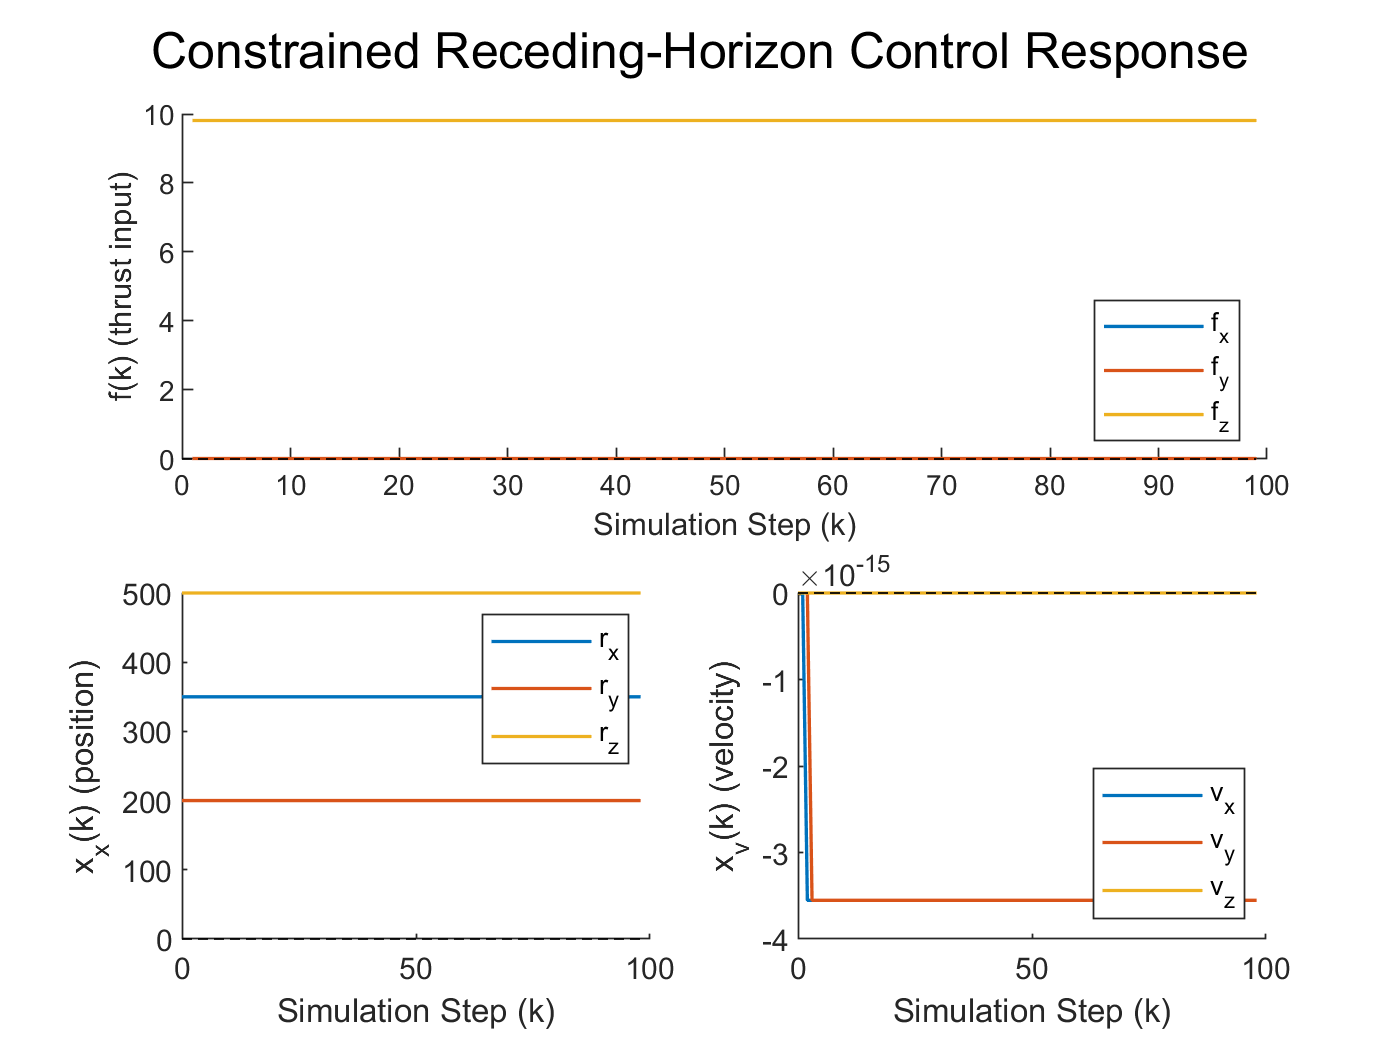


figure(7); sgtitle("Constrained Receding-Horizon Control Response");
% Plot results
subplot(2,2,[1 2]); hold on
stairs([1:nk], us(1,1:nk), "LineWidth", 1);   % plot of input and input constraints
stairs([1:nk], us(2,1:nk), "LineWidth", 1);
stairs([1:nk], us(3,1:nk)+g*mass, "LineWidth", 1);
%ylim([min(qu) max(qu)]);
subplot(2,2,3); hold on
plot([0:nk-1], ys(1,1:nk), "LineWidth", 1);     % plot of position states
plot([0:nk-1], ys(2,1:nk), "LineWidth", 1);
plot([0:nk-1], ys(3,1:nk), "LineWidth", 1);
subplot(2,2,4); hold on
plot([0:nk-1], ys(4,1:nk), "LineWidth", 1);     % plot of velocity states
plot([0:nk-1], ys(5,1:nk), "LineWidth", 1);
plot([0:nk-1], ys(6,1:nk), "LineWidth", 1);

% Plot annotations
subplot(2,2, [1 2]);    ylabel("f(k) (thrust input)");    xlabel("Simulation Step (k)");  
legend("f_x","f_y","f_z",'Location', 'southeast')
h = plot([0 nk],[0 0], 'black--', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
subplot(2,2,3);         ylabel("x_x(k) (position)");  xlabel("Simulation Step (k)"); 
legend("r_x","r_y","r_z",'Location', 'northeast')
h = plot([0 nk],[0 0], 'black--', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );
subplot(2,2,4);         ylabel("x_v(k) (velocity)");  xlabel("Simulation Step (k)");  
legend("v_x","v_y","v_z",'Location', 'southeast')
h = plot([0 nk],[0 0], 'black--', "LineWidth",.5);
hold on;    set( get( get( h, 'Annotation'), 'LegendInformation' ), 'IconDisplayStyle', 'off' );

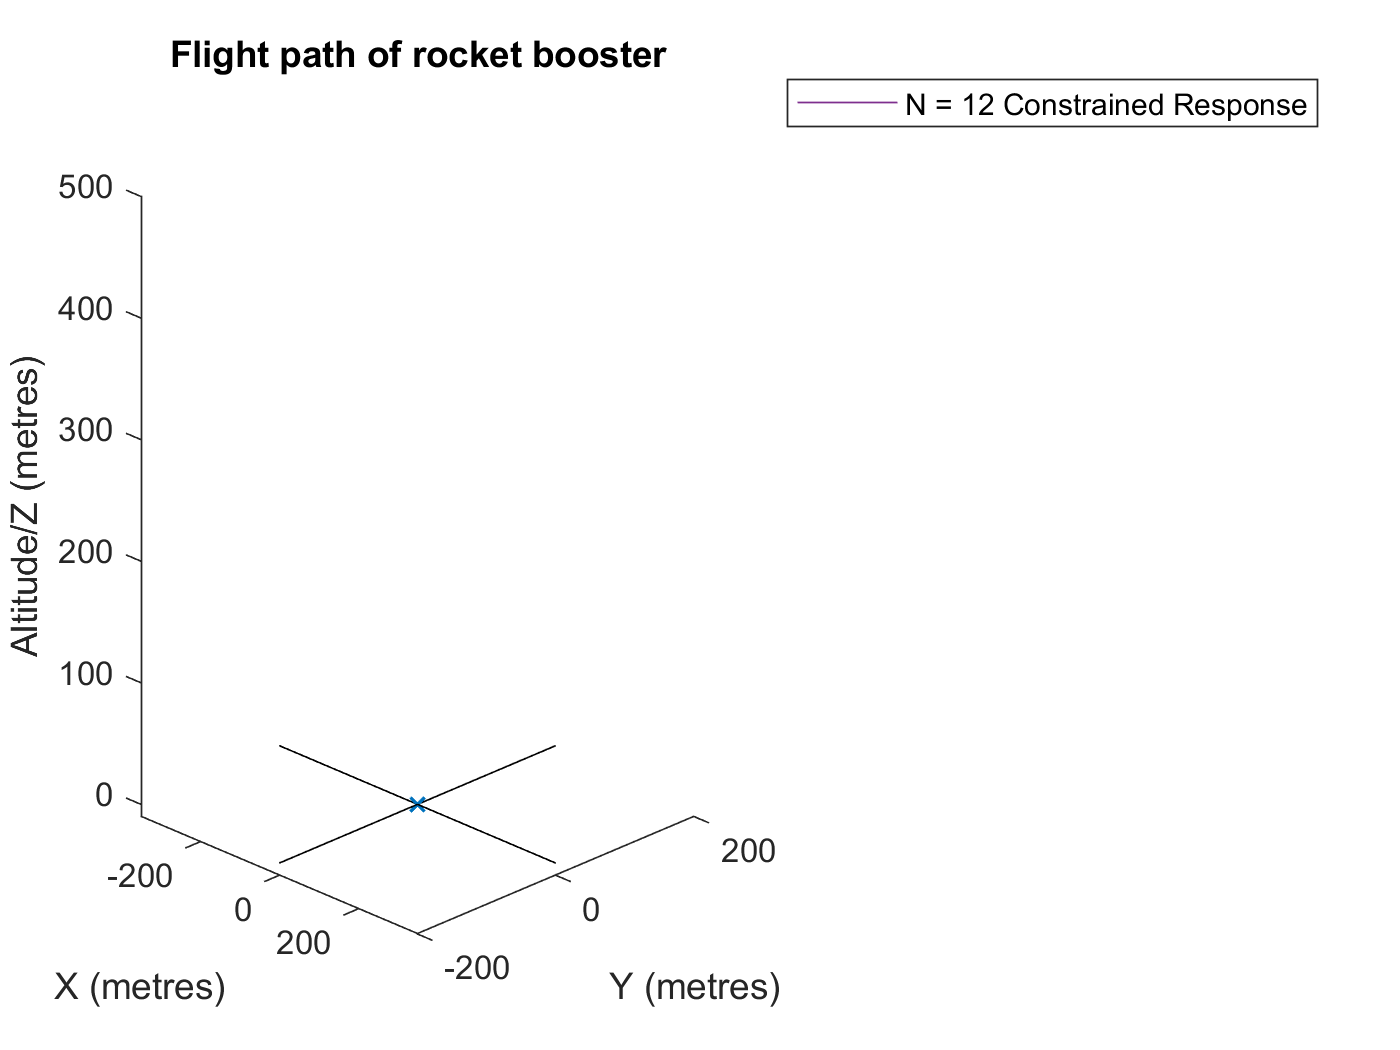


figure(1);  plot3(ys(1,1:nk), ys(2,1:nk), ys(3,1:nk), 'DisplayName', "N = "+N+" Constrained Response"); hold on